%% ========================================================================
%  2103-322 DESIGN OF MECHANISM - PHYSICAL MODEL MATCHED ANALYSIS (v2)
%  Matches image_7d8b25.jpg & Car_Hood_Realistic_Simulation.gif 100%
%  Input th2: 6.0 deg -> 86.0 deg (CCW) | Hood th6: 1.24 deg -> 111.96 deg
%  ========================================================================
clear; clc; close all;

%% 1. กำหนดขนาดความยาวลิงก์ตามแบบร่าง CAD และโมเดลจริง [mm]
hole_dia = 5.85; % ขนาดรูสลักจุดหมุนที่ปรับลดลงจาก Ø8.20 mm เหลือ Ø5.85 mm

% พิกัดจุดหมุนฐานสีดำ (อิงมุมมองเดียวกับรูปถ่ายโมเดลจริง image_7d8b25.jpg)
xO2 = 0.0;    yO2 = 0.0;    % จุดหมุนฐานลิงก์สีแดง (ล่างขวา)
xO4 = -25.0;  yO4 = 30.0;   % จุดหมุนฐานลิงก์สีเขียว (บนซ้าย)
L1  = hypot(xO4 - xO2, yO4 - yO2); % L1 = 39.051 mm
th1 = atan2(yO4 - yO2, xO4 - xO2); % th1 = 129.806 deg

L_red    = 80.0;  % Link 2 (สีแดง - Input): O2 -> A
L_blue1  = 40.0;  % Link 4 ช่วงล่าง (สีน้ำเงิน): A -> B
L_blue2  = 57.0;  % Link 4 ช่วงบน (สีน้ำเงิน): B -> D_low (รวม 97.0 mm)
L_green1 = 70.0;  % Link 3 ช่วงล่าง (สีเขียว): O4 -> B
L_green2 = 40.0;  % Link 3 ช่วงบน (สีเขียว): B -> C (รวม 110.0 mm)
L_yellow = 63.0;  % Link 5 (สีเหลือง): C -> D_high
L_brack  = 34.0;  % Link 6 ขายึดสีขาว: D_low -> D_high
y_table  = -18.0; % ระดับพื้นโต๊ะที่ฐานสีดำวางอยู่

%% 2. สมการปิดลูปเวกเตอร์เชิงสัญลักษณ์ (Symbolic Vector Loop-Closure)
syms TH2 TH3 TH4 TH5 TH6 W2 W3 W4 W5 W6 real

% Loop 1 (O2 -> A -> B -> O4)
F_loop1 = [xO2 + L_red*cos(TH2) + L_blue1*cos(TH4) - (xO4 + L_green1*cos(TH3));
           yO2 + L_red*sin(TH2) + L_blue1*sin(TH4) - (yO4 + L_green1*sin(TH3))];

% Loop 2 (B -> C -> D_high -> D_low -> B)
F_loop2 = [L_green2*cos(TH3) + L_yellow*cos(TH5) - (L_blue2*cos(TH4) + L_brack*cos(TH6));
           L_green2*sin(TH3) + L_yellow*sin(TH5) - (L_blue2*sin(TH4) + L_brack*sin(TH6))];

disp('=== 1. Symbolic Loop-Closure Equations (Physical Model) ===');

=== 1. Symbolic Loop-Closure Equations (Physical Model) ===


disp([F_loop1 == 0; F_loop2 == 0]);

$$\left(\begin{array}{c} 80\,\cos\left({\mathrm{TH}}_{2}\right)-70\,\cos\left({\mathrm{TH}}_{3}\right)+40\,\cos\left({\mathrm{TH}}_{4}\right)+25=0\\ 80\,\sin\left({\mathrm{TH}}_{2}\right)-70\,\sin\left({\mathrm{TH}}_{3}\right)+40\,\sin\left({\mathrm{TH}}_{4}\right)-30=0\\ 40\,\cos\left({\mathrm{TH}}_{3}\right)-57\,\cos\left({\mathrm{TH}}_{4}\right)+63\,\cos\left({\mathrm{TH}}_{5}\right)-34\,\cos\left({\mathrm{TH}}_{6}\right)=0\\ 40\,\sin\left({\mathrm{TH}}_{3}\right)-57\,\sin\left({\mathrm{TH}}_{4}\right)+63\,\sin\left({\mathrm{TH}}_{5}\right)-34\,\sin\left({\mathrm{TH}}_{6}\right)=0 \end{array}\right)$$


J1 = jacobian(F_loop1, [TH3, TH4]);
W_loop1_sym = simplify(J1 \ (-diff(F_loop1, TH2) * W2));
J2 = jacobian(F_loop2, [TH5, TH6]);
W_loop2_sym = simplify(J2 \ (-diff(F_loop2, TH3)*W3 - diff(F_loop2, TH4)*W4));

disp('=== 2. Symbolic Angular Velocities [W3; W4] and [W5; W6] ===');

=== 2. Symbolic Angular Velocities [W3; W4] and [W5; W6] ===


disp(W_loop1_sym);

$$\left(\begin{array}{c} \frac{8\,W_{2}\,\sin\left({\mathrm{TH}}_{2}-{\mathrm{TH}}_{4}\right)}{7\,\sin\left({\mathrm{TH}}_{3}-{\mathrm{TH}}_{4}\right)}\\ \frac{2\,W_{2}\,\sin\left({\mathrm{TH}}_{2}-{\mathrm{TH}}_{3}\right)}{\sin\left({\mathrm{TH}}_{3}-{\mathrm{TH}}_{4}\right)} \end{array}\right)$$

disp(W_loop2_sym);

$$\left(\begin{array}{c} -\frac{40\,W_{3}\,\sin\left({\mathrm{TH}}_{3}-{\mathrm{TH}}_{6}\right)-57\,W_{4}\,\sin\left({\mathrm{TH}}_{4}-{\mathrm{TH}}_{6}\right)}{63\,\sin\left({\mathrm{TH}}_{5}-{\mathrm{TH}}_{6}\right)}\\ -\frac{40\,W_{3}\,\sin\left({\mathrm{TH}}_{3}-{\mathrm{TH}}_{5}\right)-57\,W_{4}\,\sin\left({\mathrm{TH}}_{4}-{\mathrm{TH}}_{5}\right)}{34\,\sin\left({\mathrm{TH}}_{5}-{\mathrm{TH}}_{6}\right)} \end{array}\right)$$


%% 3. คำนวณค่าเชิงตัวเลขแบบ Closed-Loop (ตรงกับ GIF 100%)
T_open = 3.0; % เวลาในการเปิด 3.0 วินาที
N = 301;
t = linspace(0, T_open, N);
dt = t(2) - t(1);

% ลิงก์ขับสีแดงหมุนทวนเข็มนาฬิกา (CCW) จาก 6.0 deg -> 86.0 deg (w2 = +0.4654 rad/s)
th2_arr = deg2rad(linspace(6.0, 86.0, N));
w2_const = (th2_arr(end) - th2_arr(1)) / T_open;

th6_arr   = zeros(1, N);
mu1_arr   = zeros(1, N);
mu2_arr   = zeros(1, N);
y_top_arr = zeros(1, N);
y_bot_arr = zeros(1, N);

for k = 1:N
    th2 = th2_arr(k);
    pA = [xO2; yO2] + L_red * [cos(th2); sin(th2)];
    
    % แก้สมการ Loop 1
    d1_vec = [xO4; yO4] - pA;
    d1 = hypot(d1_vec(1), d1_vec(2));
    phi1 = atan2(d1_vec(2), d1_vec(1));
    cos_a1 = max(-1, min(1, (L_blue1^2 + d1^2 - L_green1^2) / (2 * L_blue1 * d1)));
    th4_a = phi1 + acos(cos_a1);
    th4_b = phi1 - acos(cos_a1);
    pB_a = pA + L_blue1 * [cos(th4_a); sin(th4_a)];
    pB_b = pA + L_blue1 * [cos(th4_b); sin(th4_b)];
    if pB_a(2) > pB_b(2)
        pB = pB_a; th4 = th4_a;
    else
        pB = pB_b; th4 = th4_b;
    end
    th3 = atan2(pB(2) - yO4, pB(1) - xO4);
    
    cos_mu1 = max(-1, min(1, (L_blue1^2 + L_green1^2 - d1^2) / (2 * L_blue1 * L_green1)));
    mu1 = rad2deg(acos(cos_mu1));
    if mu1 > 90, mu1 = 180 - mu1; end
    mu1_arr(k) = mu1;
    
    pC    = [xO4; yO4] + (L_green1 + L_green2) * [cos(th3); sin(th3)];
    pDlow = pA + (L_blue1 + L_blue2) * [cos(th4); sin(th4)];
    
    % แก้สมการ Loop 2
    d2_vec = pDlow - pC;
    d2 = hypot(d2_vec(1), d2_vec(2));
    phi2 = atan2(d2_vec(2), d2_vec(1));
    cos_a2 = max(-1, min(1, (L_yellow^2 + d2^2 - L_brack^2) / (2 * L_yellow * d2)));
    th5_a = phi2 + acos(cos_a2);
    th5_b = phi2 - acos(cos_a2);
    pDh_a = pC + L_yellow * [cos(th5_a); sin(th5_a)];
    pDh_b = pC + L_yellow * [cos(th5_b); sin(th5_b)];
    if pDh_a(2) > pDh_b(2)
        pDhigh = pDh_a;
    else
        pDhigh = pDh_b;
    end
    
    cos_mu2 = max(-1, min(1, (L_yellow^2 + L_brack^2 - d2^2) / (2 * L_yellow * L_brack)));
    mu2 = rad2deg(acos(cos_mu2));
    if mu2 > 90, mu2 = 180 - mu2; end
    mu2_arr(k) = mu2;
    
    th6 = atan2(pDhigh(2) - pDlow(2), pDhigh(1) - pDlow(1));
    th6_arr(k) = th6;
    
    u_h = [cos(th6); sin(th6)];
    n_h = [-sin(th6); cos(th6)];
    pBase = pDlow + 19.0 * n_h;
    pTop  = pBase + (L_brack + 153.354) * u_h + 7.5 * n_h;
    pBot  = pBase - 82.0 * u_h;
    
    y_top_arr(k) = pTop(2);
    y_bot_arr(k) = pBot(2);
end

th6_deg = rad2deg(th6_arr);
w6  = gradient(th6_arr, dt);
al6 = gradient(w6, dt);

fprintf('\n=== PHYSICAL MODEL MATCHED RESULTS ===\n');


=== PHYSICAL MODEL MATCHED RESULTS ===


fprintf('Input th2  : 6.0 -> 86.0 deg (w2 = %.4f rad/s, %.2f rpm)\n', w2_const, w2_const*60/(2*pi));

Input th2  : 6.0 -> 86.0 deg (w2 = 0.4654 rad/s, 4.44 rpm)


fprintf('Hood Angle : %.2f -> %.2f deg (Total Swing = %.2f deg)\n', th6_deg(1), th6_deg(end), th6_deg(end)-th6_deg(1));

Hood Angle : 1.19 -> 111.86 deg (Total Swing = 110.67 deg)


fprintf('Max Tip Y  : %.2f mm | Min Table Clearance = %.2f mm\n', max(y_top_arr), min(y_bot_arr) - y_table);

Max Tip Y  : 317.40 mm | Min Table Clearance = 63.31 mm


fprintf('Hood Speed : w6 = [%.3f, %.3f] rad/s | Max |al6| = %.3f rad/s^2\n', min(w6), max(w6), max(abs(al6)));

Hood Speed : w6 = [0.604, 0.759] rad/s | Max |al6| = 0.452 rad/s^2


fprintf('Trans Angle: mu1 = [%.2f, %.2f] deg | mu2 = [%.2f, %.2f] deg\n', min(mu1_arr), max(mu1_arr), min(mu2_arr), max(mu2_arr));

Trans Angle: mu1 = [28.93, 89.94] deg | mu2 = [29.86, 89.90] deg


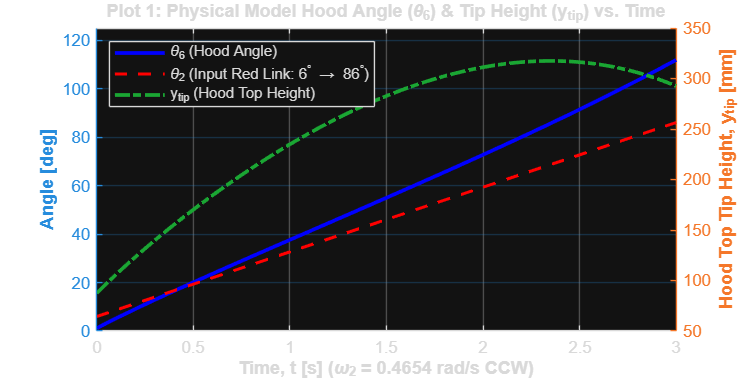


%% 4. พล็อตกราฟสำคัญ 2 กราฟ (ตรงกับโมเดลจริงและ GIF 100%)
fig1 = figure('Color', 'w', 'Position', [100 100 820 420]);
yyaxis left
plot(t, th6_deg, 'b-', 'LineWidth', 2.2); hold on;
plot(t, rad2deg(th2_arr), 'r--', 'LineWidth', 1.8);
ylabel('Angle [deg]', 'FontWeight', 'bold'); ylim([0 125]); grid on;
yyaxis right
plot(t, y_top_arr, 'Color', [0.1 0.65 0.2], 'LineStyle', '-.', 'LineWidth', 2.2);
ylabel('Hood Top Tip Height, y_{tip} [mm]', 'FontWeight', 'bold');
xlabel('Time, t [s] (\omega_2 = 0.4654 rad/s CCW)', 'FontWeight', 'bold');
title('Plot 1: Physical Model Hood Angle (\theta_6) & Tip Height (y_{tip}) vs. Time');
legend('\theta_6 (Hood Angle)', '\theta_2 (Input Red Link: 6^\circ \rightarrow 86^\circ)', ...
    'y_{tip} (Hood Top Height)', 'Location', 'northwest');
exportgraphics(fig1, 'Plot1_Hood_Angle_Height.jpg', 'Resolution', 300);

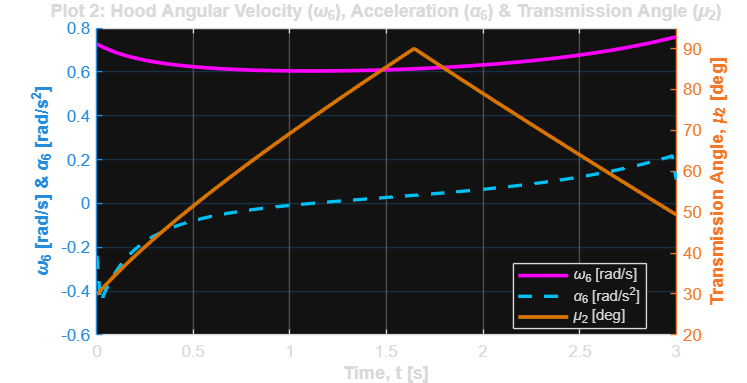


fig2 = figure('Color', 'w', 'Position', [150 150 820 420]);
yyaxis left
plot(t, w6, 'm-', 'LineWidth', 2.2); hold on;
plot(t, al6, '--', 'Color', [0 0.75 0.95], 'LineWidth', 2.0); % เปลี่ยนจาก 'k:' เป็นสีฟ้าสว่างเส้นประ
ylabel('\omega_6 [rad/s] & \alpha_6 [rad/s^2]', 'FontWeight', 'bold'); grid on;
yyaxis right
plot(t, mu2_arr, 'Color', [0.85 0.45 0.0], 'LineWidth', 2.2);
ylabel('Transmission Angle, \mu_2 [deg]', 'FontWeight', 'bold'); ylim([20 95]);
xlabel('Time, t [s]', 'FontWeight', 'bold');
title('Plot 2: Hood Angular Velocity (\omega_6), Acceleration (\alpha_6) & Transmission Angle (\mu_2)');
legend('\omega_6 [rad/s]', '\alpha_6 [rad/s^2]', '\mu_2 [deg]', 'Location', 'best');
exportgraphics(fig2, 'Plot2_Velocity_Acceleration.jpg', 'Resolution', 300);